## nirs.modules.default_modules.image_recon

This module runs a default modules (basic processing) to get image reconstruction result. It is noted that the raw data must have a Probe1020 object. 

The following modules are included in this default: nirs.modules.RemoveStimLess, nirs.modules.FixNaNs, nirs.modules.Resample, nirs.modules.OpticalDensity, and nirs.modules.TrimBaseLine, nirs.modules.GLM, and nirs.modules.ImageRecondMFX.

**Example Usage: **

raw = nirs.testing.simData_registered();

job = nirs.modules.default_modules.image_recon;
ImageStats = job.run(raw);

Import data module skipped: Data provided
dOD created in workspace
.......Finished    1 of    1.
SubjStats created in workspace
  ReML Iteration: 7   ...6.642106e-05

ImageStats created in workspace


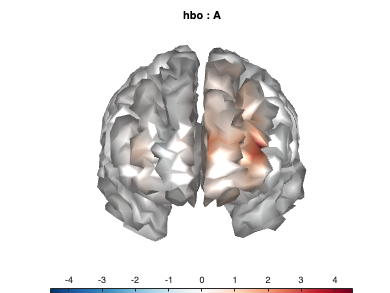

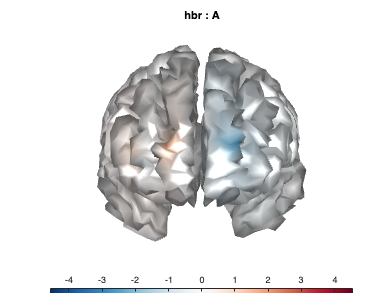

ans =    12.0012   13.0012



ImageStats.draw

**References**

[1] Abdelnour F, Schmidt B, Huppert TJ. Topographic localization of brain activation in diffuse optical imaging using spherical wavelets. Phys Med Biol. 2009 Oct 21;54(20):6383-413. doi: 10.1088/0031-9155/54/20/023. Epub 2009 Oct 7. PMID: 19809125; PMCID: PMC2806654. [https://pubmed.ncbi.nlm.nih.gov/19809125/](https://pubmed.ncbi.nlm.nih.gov/19809125/)

[2] Abdelnour F, Huppert T. A random-effects model for group-level analysis of diffuse optical brain imaging. Biomed Opt Express. 2010 Nov 30;2(1):1-25. doi: 10.1364/BOE.2.000001. PMID: 21326631; PMCID: PMC3028484. [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3028484/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3028484/)

[3] Abdelnour F, Genovese C, Huppert T. Hierarchical Bayesian regularization of reconstructions for diffuse optical tomography using multiple priors. Biomed Opt Express. 2010 Oct 6;1(4):1084-1103. doi: 10.1364/BOE.1.001084. PMID: 21258532; PMCID: PMC3018091. [https://pubmed.ncbi.nlm.nih.gov/21258532/](https://pubmed.ncbi.nlm.nih.gov/21258532/) 